**Private Equity Investment**

**Investment Parameters**

% Investment parameters
initial_investment = 100; % million dollars
hurdle_rate_annual = 0.08; % 8% per annum
gross_return_rate_annual = 0.15; % 15% per annum
carried_interest_rate = 0.20; % 20%
investment_period_years = 5; % years
months = investment_period_years * 12; % total months

% Convert annual rates to monthly rates
hurdle_rate_monthly = (1 + hurdle_rate_annual)^(1/12) - 1;
gross_return_rate_monthly = (1 + gross_return_rate_annual)^(1/12) - 1;


**Key Data Variables**

% Initialize arrays to store values
dates = datetime(0,0,0) + calmonths(1:months);
fund_value = zeros(months, 1);
preferred_return = zeros(months, 1);
total_profits = zeros(months, 1);
excess_profits = zeros(months, 1);
carried_interest = zeros(months, 1);
net_profits_for_lps = zeros(months, 1);
total_return_to_lps = zeros(months, 1);


**Calculate Key Variables Over Time**

% Initial values
fund_value(1) = initial_investment;
preferred_return(1) = initial_investment;
total_return_to_lps(1) = initial_investment;

% Loop to calculate values for each month
for i = 2:months
    fund_value(i) = fund_value(i-1) * (1 + gross_return_rate_monthly);
    preferred_return(i) = initial_investment * (1 + hurdle_rate_monthly)^i;
    total_profits(i) = fund_value(i) - initial_investment;
    excess_profits(i) = total_profits(i) - (preferred_return(i) - initial_investment);
    carried_interest(i) = max(0, carried_interest_rate * excess_profits(i));
    net_profits_for_lps(i) = total_profits(i) - carried_interest(i);
    total_return_to_lps(i) = initial_investment + (preferred_return(i) - initial_investment) + net_profits_for_lps(i);
end

% Create timetable
results = timetable(dates', fund_value, preferred_return, total_profits, ...
    excess_profits, carried_interest, net_profits_for_lps, total_return_to_lps, ...
    'VariableNames', {'FundValue', 'PreferredReturn', 'TotalProfits', ...
    'ExcessProfits', 'CarriedInterest', 'NetProfitsForLPs', 'TotalReturnToLPs'});

% Display the results
disp(results);

        Time        FundValue    PreferredReturn    TotalProfits    ExcessProfits    CarriedInterest    NetProfitsForLPs    TotalReturnToLPs
    ____________    _________    _______________    ____________    _____________    _______________    ________________    ________________

    30-Dec--0001        100             100                 0                0                 0                  0                 100     
    30-Jan-0000      101.17          101.29            1.1715         -0.11945                 0             1.1715              102.46     
    29-Feb-0000      102.36          101.94            2.3567          0.41405          0.082811             2.2

**Visualize Growth of the Private Equity Investment Over Time**

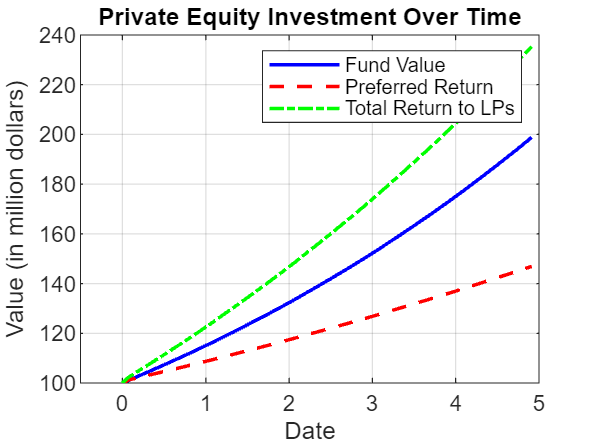

% Plot the results
figure;
plot(results.Time, results.FundValue, 'b-', 'LineWidth', 1.5); hold on;
plot(results.Time, results.PreferredReturn, 'r--', 'LineWidth', 1.5);
plot(results.Time, results.TotalReturnToLPs, 'g-.', 'LineWidth', 1.5);
xlabel('Date');
ylabel('Value (in million dollars)');
title('Private Equity Investment Over Time');
legend('Fund Value', 'Preferred Return', 'Total Return to LPs');
grid on;